% === BASE PARAMETERS (MORE AGGRESSIVE THERAPY) ===
baseParams = struct();
baseParams.dd = 0.06;              % even slower chemo decay (longer persistence)
baseParams.bk = 3.5e-6;            % much stronger chemo-tumor interaction
baseParams.epsilon = 1e-3;         % unchanged (saturation)
baseParams.b = 0.45;               % significantly increased chemo killing power
baseParams.dc = 0.103;             % tumor natural death rate
baseParams.lambda_CE = 0.4579;     % tumor growth rate
baseParams.Cr = 1e4;               % tumor carrying capacity
baseParams.lambda_V0 = 1e-3;       % VEGF production
baseParams.dv = 0.1;               % VEGF decay
baseParams.muB = 35;               % much stronger anti-VEGF effect
baseParams.lambda_E = 0.03;        % endothelial growth
baseParams.EH = 10;                % endothelial carrying cap
baseParams.k = 1;                  % endothelial response
baseParams.Ethres = 4.5;           % VEGF sensitivity threshold
baseParams.de = 0.05;              % endothelial decay
baseParams.db = 0.02;              % slower AV decay (longer persistence)
baseParams.muBK = 0.45;            % significantly stronger VEGF clearance by AV

% === PARAMETER VARIATIONS TABLE (% changes) ===
variationTable = [
    +20, -10, +50, -30;
    -15, -20, +20, +10;
    +50, +35, -10, +50;
    -30, +5,  +10, -15;
    +5,  +10, -20, +20
]; % rows = patients 1-5, cols = lambda_CE, Cr, lambda_V0, dd

% === TIME SPAN & INITIAL CONDITIONS ===
tspan = [0 50];
Y0 = [0.01, 50, 0.5, 1.5, 0.01];  % D, C, V, E, AV

% === VARIABLES TO STORE RESULTS ===
T_all = cell(5,1);
Y_all = cell(5,1);

% Interpolation grid for averaging
T_uniform = linspace(tspan(1), tspan(2), 200)';
Y_interp = zeros(length(T_uniform), 5, 5); % time x var x patient

% === SIMULATION LOOP FOR EACH PATIENT ===
for i = 1:5
    % Apply variation
    p = baseParams;
    p.lambda_CE = p.lambda_CE * (1 + variationTable(i,1)/100);
    p.Cr        = p.Cr        * (1 + variationTable(i,2)/100);
    p.lambda_V0 = p.lambda_V0 * (1 + variationTable(i,3)/100);
    p.dd        = p.dd        * (1 + variationTable(i,4)/100);

    % Solve ODE
    [T, Y] = ode15s(@(t,Y) tumorODE(t, Y, p), tspan, Y0);

    % Store original
    T_all{i} = T;
    Y_all{i} = Y;

    % Interpolate to uniform time grid
    for j = 1:5  % for each variable
        Y_interp(:,j,i) = interp1(T, Y(:,j), T_uniform, 'linear', 'extrap');
    end
end


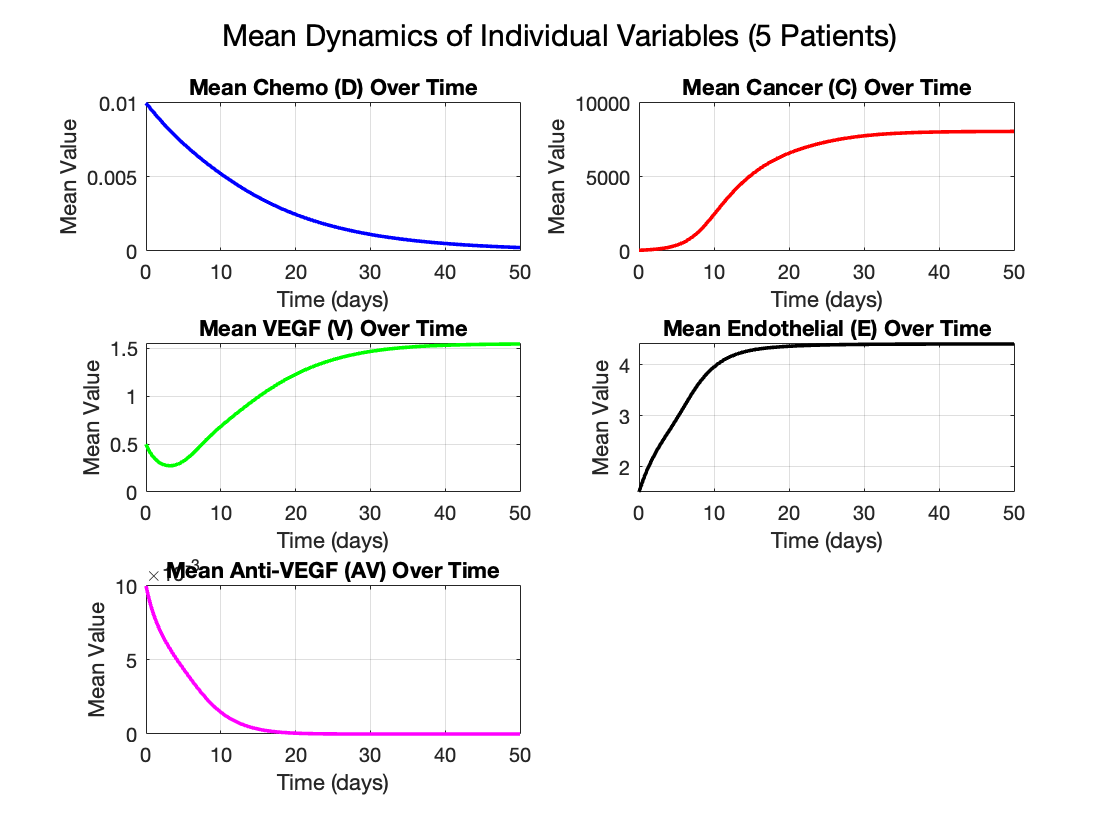

% === Compute mean across patients ===
Y_mean = mean(Y_interp, 3);  % average across 3rd dimension (patients)

% === Plot each variable in a separate subplot ===
figure;
varNames = {'Chemo (D)', 'Cancer (C)', 'VEGF (V)', 'Endothelial (E)', 'Anti-VEGF (AV)'};
colors = {'b', 'r', 'g', 'k', 'm'};

for i = 1:5
    subplot(3,2,i)
    plot(T_uniform, Y_mean(:,i), 'Color', colors{i}, 'LineWidth', 1.8);
    title(['Mean ' varNames{i} ' Over Time']);
    xlabel('Time (days)');
    ylabel('Mean Value');
    grid on;
end
sgtitle('Mean Dynamics of Individual Variables (5 Patients)');

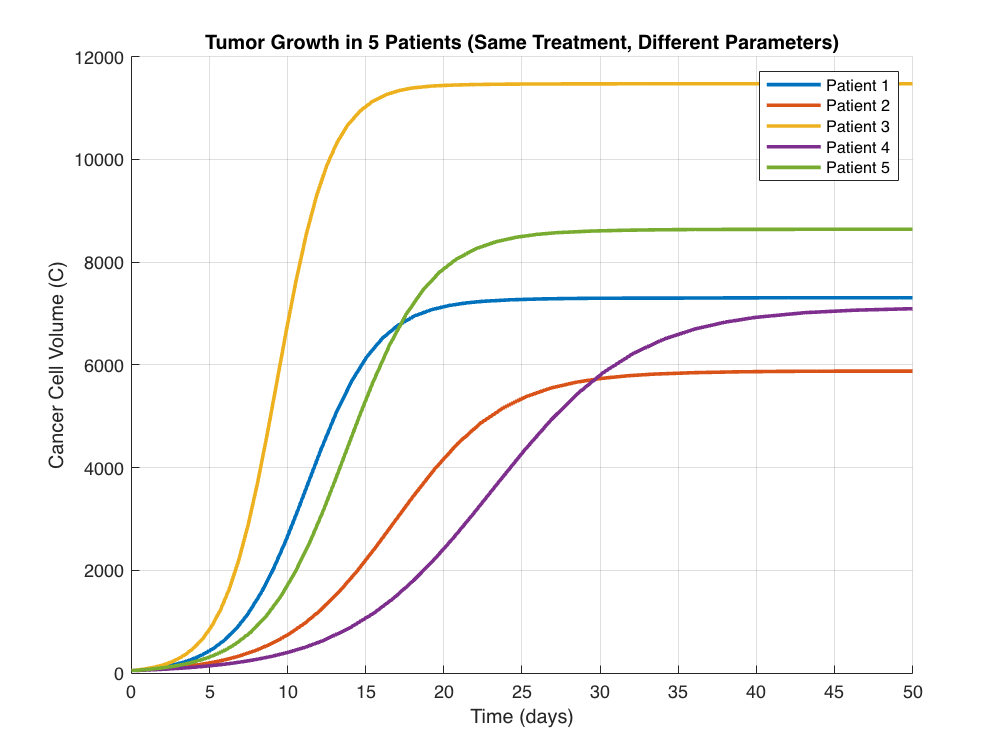


% === PLOT INDIVIDUAL CANCER GROWTH TRAJECTORIES ===
figure;
hold on;
colors = lines(5);
for i = 1:5
    plot(T_all{i}, Y_all{i}(:,2), 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel('Time (days)');
ylabel('Cancer Cell Volume (C)');
title('Tumor Growth in 5 Patients (Same Treatment, Different Parameters)');
legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5');
grid on;

Patient 2 optimization (high-dose strategy):


  Best Chemo dose (D):        1.2000 mg/ml


  Best Anti-VEGF dose (AV):   2.4000 mg/ml


  Best AV/Chemo Ratio:        2.00


  Final tumor volume (treated): 43.15


  Control tumor volume:         4568.33


  Tumor volume reduction:       99.06 %



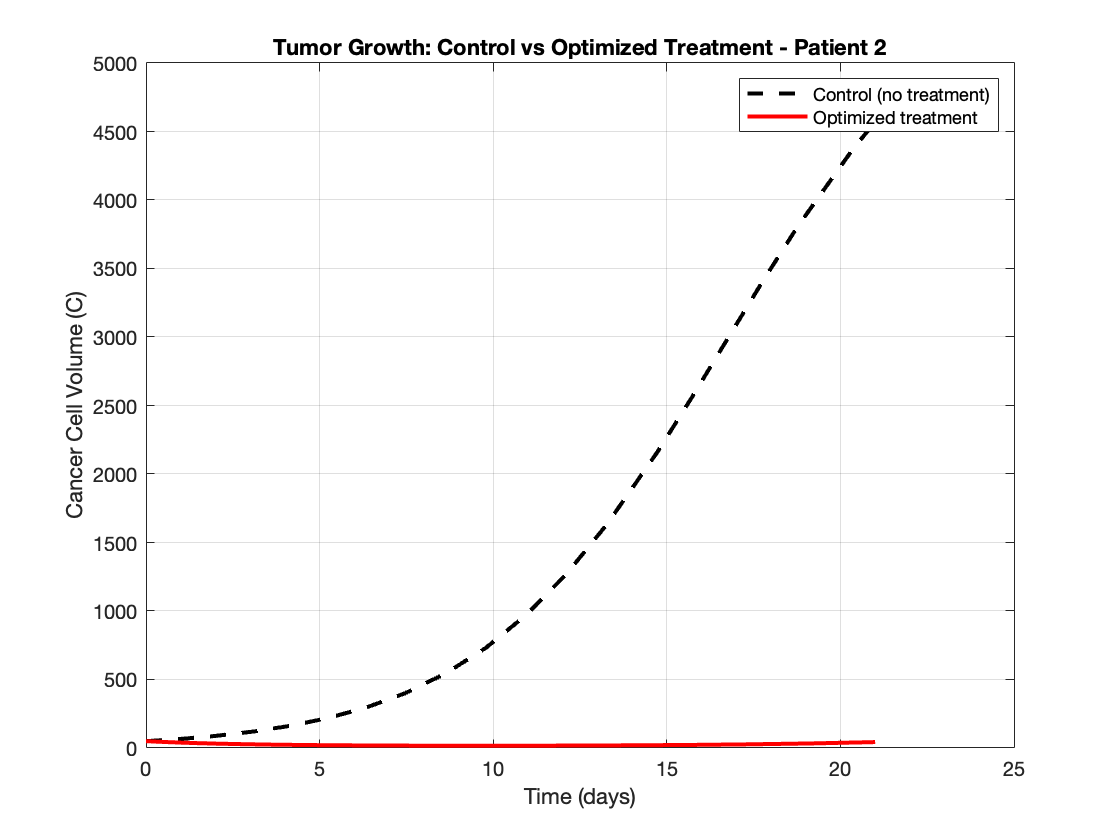

Patient 3 optimization (high-dose strategy):


  Best Chemo dose (D):        1.2000 mg/ml


  Best Anti-VEGF dose (AV):   2.7692 mg/ml


  Best AV/Chemo Ratio:        2.31


  Final tumor volume (treated): 8451.39


  Control tumor volume:         11461.34


  Tumor volume reduction:       26.26 %



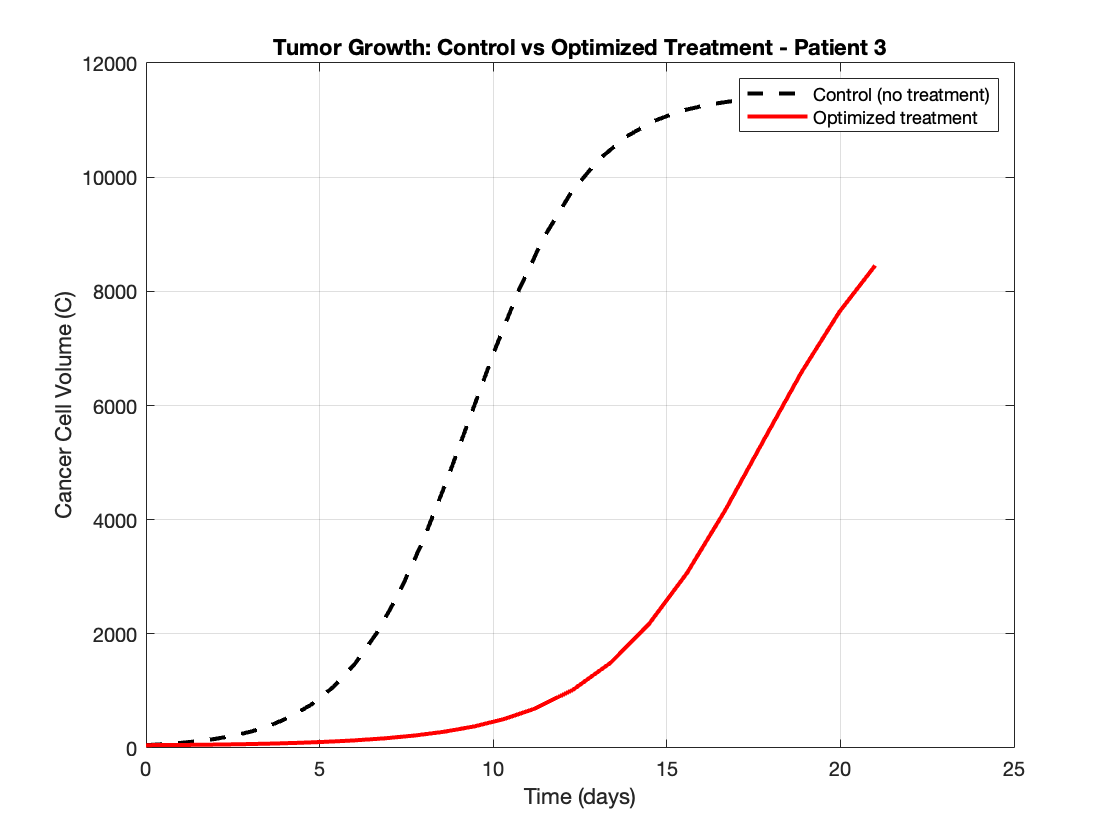

% === VARIATIONS FOR PATIENT 2 (slow) AND 3 (fast) ===
variationTable = [
    -15, -20, +20, +10;  % Patient 2
    +50, +35, -10, +50   % Patient 3
];

% === ALLOWED DOSE RANGES (Aggressive Clinical Implementation) ===
D_vals = linspace(1.0, 1.2, 10);           % High chemo dose range in mg/mL
ratio_vals = linspace(2, 5, 40);           % High AV/Chemo ratios
AV_min = 2.0;                              % Minimum high AV dose in mg/mL
AV_max = 5.0;                              % Maximum high AV dose in mg/mL

% === TIME SPAN FOR SIMULATION ===
tspan = [0 21];

% === Loop over both patients ===
for patientIdx = 2:3
    % Setup patient-specific parameters
    p = baseParams;
    row = variationTable(patientIdx-1, :);
    p.lambda_CE = p.lambda_CE * (1 + row(1)/100);
    p.Cr        = p.Cr        * (1 + row(2)/100);
    p.lambda_V0 = p.lambda_V0 * (1 + row(3)/100);
    p.dd        = p.dd        * (1 + row(4)/100);

    % Simulate control (no treatment)
    Y0_control = [0, 50, 0.5, 1.5, 0];
    [Tctrl, Yctrl] = ode15s(@(t,Y) tumorODE(t,Y,p), tspan, Y0_control);
    finalTumorControl = Yctrl(end,2);

    % Optimization tracking
    minTumor = inf;
    bestD = NaN;
    bestAV = NaN;
    bestRatio = NaN;

    % Grid search with dose constraints
    for ratio = ratio_vals
        for D = D_vals
            AV = ratio * D;
            if AV < AV_min || AV > AV_max
                continue;
            end
            Y0 = [D, 50, 0.5, 1.5, AV];
            [~, Y] = ode15s(@(t,Y) tumorODE(t,Y,p), tspan, Y0);
            finalTumor = Y(end,2);
            if finalTumor < minTumor
                minTumor = finalTumor;
                bestD = D;
                bestAV = AV;
                bestRatio = ratio;
            end
        end
    end

    % === OUTPUT RESULTS ===
    fprintf('Patient %d optimization (high-dose strategy):\n', patientIdx);
    fprintf('  Best Chemo dose (D):        %.4f mg/ml\n', bestD);
    fprintf('  Best Anti-VEGF dose (AV):   %.4f mg/ml\n', bestAV);
    fprintf('  Best AV/Chemo Ratio:        %.2f\n', bestRatio);
    fprintf('  Final tumor volume (treated): %.2f\n', minTumor);
    fprintf('  Control tumor volume:         %.2f\n', finalTumorControl);
    fprintf('  Tumor volume reduction:       %.2f %%\n\n', ...
        100 * (finalTumorControl - minTumor) / finalTumorControl);

    % === Simulate optimized treatment ===
    Y0_opt = [bestD, 50, 0.5, 1.5, bestAV];
    [Topt, Yopt] = ode15s(@(t,Y) tumorODE(t,Y,p), tspan, Y0_opt);

    % === Plot comparison ===
    figure;
    plot(Tctrl, Yctrl(:,2), 'k--', 'LineWidth', 2); hold on;
    plot(Topt, Yopt(:,2), 'r-', 'LineWidth', 2);
    xlabel('Time (days)');
    ylabel('Cancer Cell Volume (C)');
    title(sprintf('Tumor Growth: Control vs Optimized Treatment - Patient %d', patientIdx));
    legend('Control (no treatment)', 'Optimized treatment');
    grid on;
end

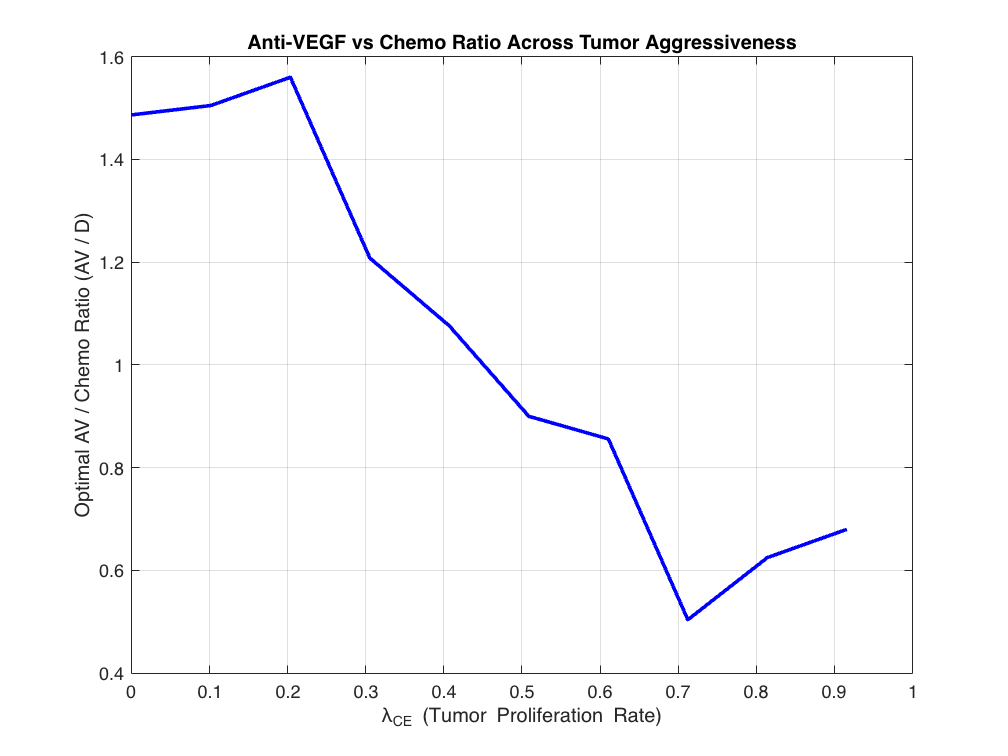

% === BASE PARAMETERS ===
lambda_CE_mean = baseParams.lambda_CE;
lambda_CE_values = linspace(0.0, 2.0, 10) * lambda_CE_mean;  % 0% to 200% of base

% === DOSE GRIDS ===
D_vals = linspace(0.001, 0.05, 10);     % chemo doses in mg/mL
AV_vals = linspace(0.001, 0.1, 10);     % anti-VEGF doses in mg/mL

% === TIME SPAN & INITIAL CONDITIONS ===
tspan = [0 21];
C0 = 50;
Y0_template = [NaN, C0, 0.5, 1.5, NaN];

% === OUTPUT VECTORS ===
av_chemo_ratio = NaN(1, 10);     % AV / D
finalTumors = NaN(1, 10);        % final tumor volume

% === SIMULATION LOOP ACROSS AGGRESSIVENESS LEVELS ===
for i = 1:10
    p = baseParams;
    p.lambda_CE = lambda_CE_values(i);  % vary tumor proliferation

    bestScore = inf;
    bestD = NaN;
    bestAV = NaN;

    for d = D_vals
        for av = AV_vals
            Y0 = Y0_template;
            Y0(1) = d;
            Y0(5) = av;
            [~, Y] = ode15s(@(t,Y) tumorODE(t,Y,p), tspan, Y0);
            finalTumor = Y(end,2);

            if finalTumor < bestScore && finalTumor > 0
                bestScore = finalTumor;
                bestD = d;
                bestAV = av;
            end
        end
    end

    finalTumors(i) = bestScore;

    % === Compute AV / Chemo Ratio ===
    if bestD < 1e-6
        av_chemo_ratio(i) = NaN;
    else
        av_chemo_ratio(i) = bestAV / bestD;
    end
end

% === SMOOTH AND PLOT ===
av_chemo_ratio_smooth = smoothdata(av_chemo_ratio, 'movmean', 5);

figure;
plot(lambda_CE_values, av_chemo_ratio_smooth, 'b-', 'LineWidth', 2);
xlabel('\lambda_{CE} (Tumor Proliferation Rate)');
ylabel('Optimal AV / Chemo Ratio (AV / D)');
title('Anti-VEGF vs Chemo Ratio Across Tumor Aggressiveness');
grid on;

% === ODE FUNCTION ===

function dYdt = tumorODE(~, Y, p)
    D = Y(1); C = max(Y(2), 0); V = max(Y(3), 0); 
    E = max(Y(4), 1e-6); AV = max(Y(5), 0);

    dDdt = -p.dd * D - p.bk * C * D * (E / (E + p.epsilon));
    dCdt = p.lambda_CE * (1 - C / p.Cr) * (E / (E + p.epsilon)) * C ...
         - p.b * (E / (E + p.epsilon)) * C * D - p.dc * C;
    dVdt = p.lambda_V0 * C * (1 - E / p.Ethres) * (1 - V / 10) ...
         - p.dv * V - p.muB * V * AV;
    dEdt = p.lambda_E * (1 - E / p.EH) * E + p.k * V * E * (1 - E / p.Ethres) - p.de * E;
    dAVdt = -p.db * AV - p.muBK * V * AV;

    dYdt = [dDdt; dCdt; dVdt; dEdt; dAVdt];
end
